# Orbital Mechanics Project - Mars Sample Return

By: Harrison Perone

Date: 4/28/25

## Overview

This project aims to calculate all of the orbital maneuvers required to complete the "Orbiter" half of the NASA / ESA Mars Sample Return mission. This means reaching Earth orbit, transferring to Mars, being captured into orbit around Mars, rendezvousing with the sample canister, and escaping Mars orbit to get back to Earth. In this context, a maneuver is a delta-V vector applied at a specific time. All the maneuvers were calculated with MATLAB scripts and functions. Simulink simulations corresponding to the different phases of the mission are used to verify the correctness of these maneuvers.

## Definitions

### Coordinate Systems

#### Solar Ecliptic

This coordinate system is fixed relative to the background stars.

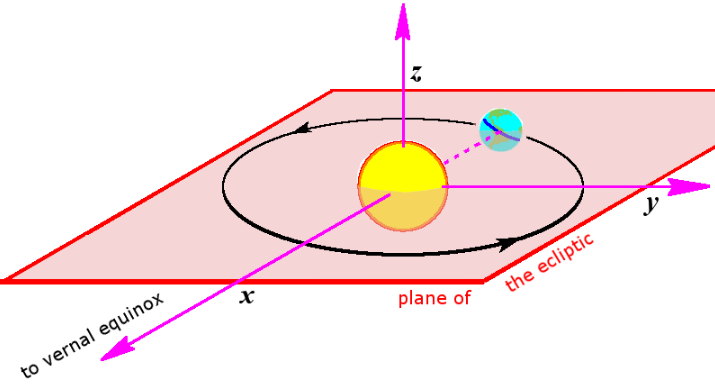

Origin: Center of the Sun

Positive x: Points in the direction of the Sun (as seen from Earth) on the Vernal Equinox. In other words, it's the point on the night sky that defines 0 right assencion.

Positive z: In the direction of Earth's orbital angular momentum vector.

Positive y: Completes right handed triad.

#### Earth-fixed Equatorial

This coordinate system rotates as Earth rotates on its axis.

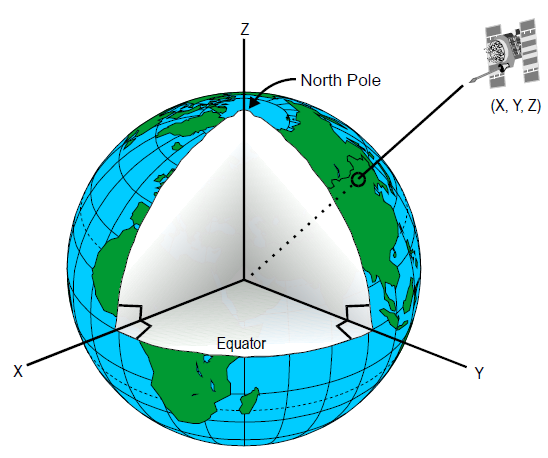

Origin: Center of the Earth

Positive x: Points towards the Prime Meridian (0 longitude)

Positive z: Points towards the north pole

Positive y: Completes right handed triad.

#### Earth-centered Ecliptic

This coordinate system is fixed relative to the background stars.

Origin: Center of the Earth

Directions are the same as the same as the Solar Ecliptic coordinate system.

### Keplerian Orbital Elements

Used to define the size, shape, and orinetation of an orbit

- h - specific angular momentum

- i - inclination

- $\Omega$ - right ascension of the ascending node

- e - eccentricity

- $\omega$ - argument of perigee

- $\upsilon$ - true anomaly

Note that specific angular momentum is found by dividing the angular mometum of an obiting object by its mass. The elements for the orientation of the orbit are visualized in the diagram below.

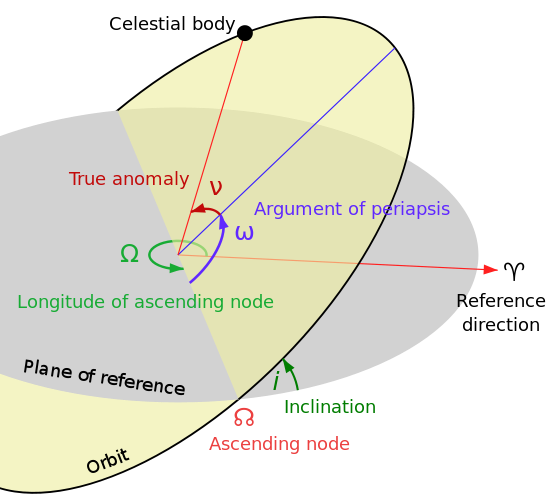

Note that the reference direction is often defined to be the positive x axis of the coordinate system in use.

## Mission Phases

### Transfers Between Earth and Mars

#### Introduction

An interplanetary trajectory is a heliocentric orbit that takes a spacecraft from one planet to another. For this project, the transfers from Earth to Mars and vice versa need to be calculated. Although neither of these steps is first chronologically, it makes sense to start with them since the launch to Earth orbit requires the information about the Earth to Mars transfer.

#### Simplifying Assumptions

Assume Earth and Mars follow circular orbits around the Sun at their mean orbital radii and that their orbits lie in the same plane. Given the sizes of Earth and Mars relative to their orbits, this assumption would lead to large errors in real life. However, its results can still be used for mission planning purpouses.

#### Problem Statement

Given the initial angles of Earth and Mars relative to the vernal equinox, find the impluse manuvers in the Solar Ecliptic frame required to transfer from one planet to the other. Fuel usage should be minimized, and as such, the spacecraft can wait at the planet of origin unitl its transfer window arrives.

#### Solution

Constants and initial conditions are set in the Hohmann_setup.m script. It calls the hohmann_transfer.m function to compute the first transfer, finds the new angles of the planets after the first transfer, and runs hohmann_transfer.m again for the return trip.

run("Hohmann_setup.m")

#### Verification

To make sure that the spacecraft stays at Earth before the start of the burn and reaches Mars by the end of the transfer, run the simulation Hohmann_outbound_sim.slx.

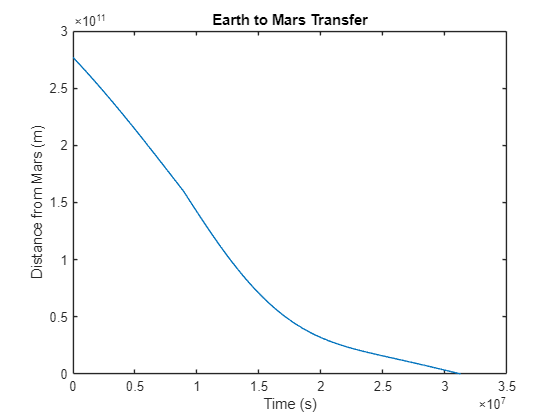

simOut = sim("Hohmann_outbound_sim.slx", 'ReturnWorkspaceOutputs', 'on');

plot_signal(simOut,"mars_dist","Distance from Mars (m)","Earth to Mars Transfer")

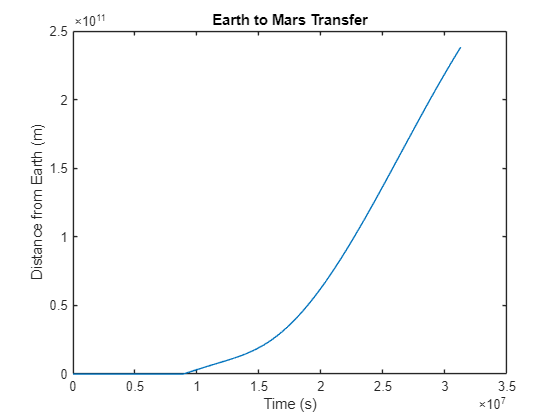

plot_signal(simOut,"earth_dist","Distance from Earth (m)","Earth to Mars Transfer")

The return trip can also be verified with a nearly identical simulation: Hohmann_inbound_sim.slx. Note that t=0 for this new simulation is the end of the previous simulation.

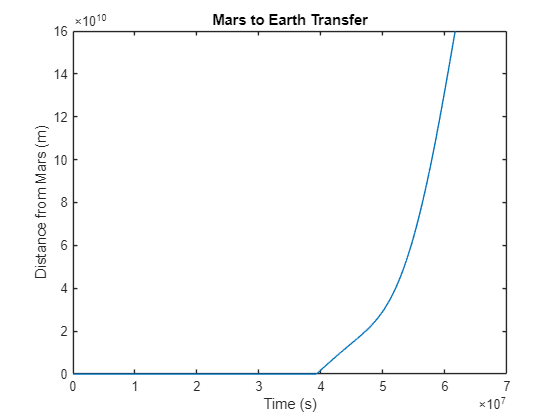

simOut = sim("Hohmann_inbound_sim.slx", 'ReturnWorkspaceOutputs', 'on');

plot_signal(simOut,"mars_dist","Distance from Mars (m)","Mars to Earth Transfer")

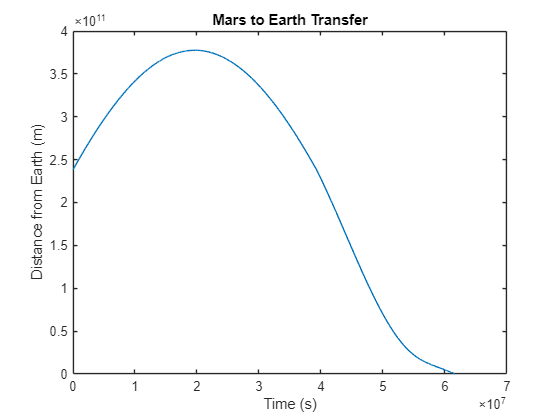

plot_signal(simOut,"earth_dist","Distance from Earth (m)","Mars to Earth Transfer")